We’ve talked about least-squares fitting, and we’ve talked about the Fourier trans- form, so it’s time for us to test both strategies out using the same data set. Here we’ll use the automated pressure data from the Scripps Pier. Use the function that you wrote previously. 				

For 2021, we will use data records 70521 through 88190, since these are nearly evenly spaced in time. There are 4 gaps, that we will need to fill. 

df = Scripps_Pier

df = struct with fields:
        time: [1892420×1 double]
           t: [1892420×1 double]
           p: [1892420×1 double]
    datetime: [1892420×6 double]


%index out 2021 only, and grab only the required rows.
idx = find(df.datetime(:,1) >= 2021 & df.datetime(:,1) < 2022);

% idx = idx(startline:endline,:);
df2021 = struct;
df2021.time = df.time(idx,:);
df2021.datetime = df.datetime(idx,:);
df2021.p = df.p(idx,:);

startline=70521;
endline=88190;
%fill gaps
xx=startline:endline;
N=(df2021.time(endline)-df2021.time(startline))/240;
time2=double(df2021.time(startline))+240*(0:N);
% gaps at 2420, 4952, 7496, 15042
df2021.p2(1:2420)=df2021.p(xx(1:2420));
df2021.p2(2421)=0.5*sum(df2021.p(xx(2420:2421)));
df2021.p2(2422:4953)=df2021.p(xx(2421:4952));
df2021.p2(4954)=0.5*sum(df2021.p(xx(4952:4953)));
df2021.p2(4955:7498)=df2021.p(xx(4953:7496));
df2021.p2(7499)=0.5*sum(df2021.p(xx(7496:7497)));
df2021.p2(7500:15045)=df2021.p(xx(7497:15042));
df2021.p2(15046)=0.5*sum(df2021.p(xx(15042:15043)));
df2021.p2(15047:length(xx)+4)=df2021.p(xx(15043:end));

1. Visual evaluation. Plot the time series of pressure data from 2021, and examine the time increments between adjacent measurements. (You can do this in Matlab using the “diff” command or in python using “numpy.diff”, for example.) Are the data always uniformly spaced? What is the increment between measurements? How long is the time record? Are there other portions of the 2021 record that also have reliable uniform spacing?

- The data are always uniformly spaced 4 minutes apart. However, there are 4 missing pressure values in the section of time that we are looking at specifically.

- The time record we are studying is just under 2 months.

- The 2021 time record is reliable except for a gap in measurements in September.

timestep = diff(df2021.datetime)

timestep =      0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0
     0     0     0     0     4     0


timestep = sum(timestep,2)

timestep =      4
     4
     4
     4
     4
     4
     4
     4
     4
     4


gaps = find(timestep >= 0 & timestep <= 0)


gaps =

  0×1 empty double column vector



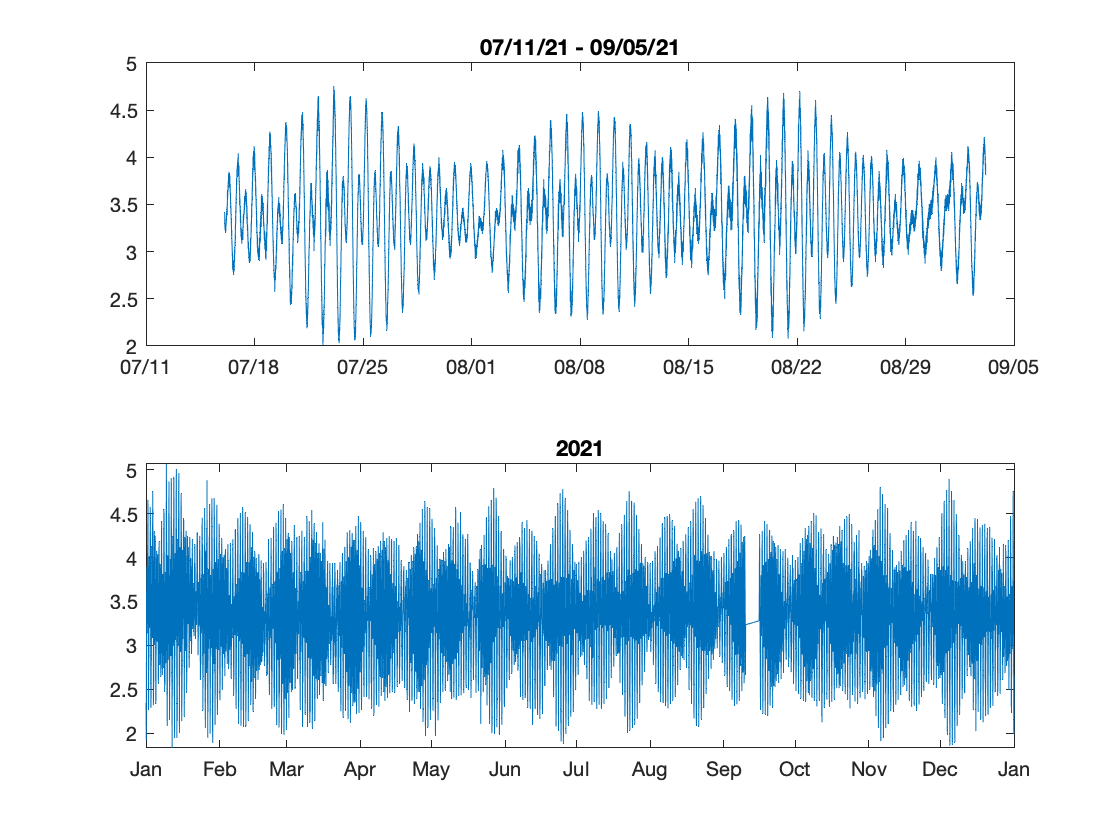

figure(1)
clf
m = tiledlayout(2,1);
nexttile
plot(df2021.time(startline:endline,:),df2021.p(startline:endline,:))
title('07/11/21 - 09/05/21')
datetick
nexttile
plot(df2021.time,df2021.p)
title('2021')
datetick

2. Least-squares fit. Least-squares fit a mean and 3 major tidal constituents to your data. Plot the raw and model solution. 

What is the mean, and what are the total amplitudes of the tidal constituents? (Total amplitude should be determined from the square root of the sum of the squares of the sine and cosine amplitudes.) 

- mean: 3.4096

- Amplitude 0.6497

P_M2=12.42;
P_K1=23.93;
P_O1=25.82;
time = (1:1:length(df2021.p2))'/(60/4); %units of hours
data = df2021.p2';
A2=[ones(length(time),1) sin(2*pi*time/P_M2) cos(2*pi*time/P_M2) sin(2*pi*time/P_K1) cos(2*pi*time/P_K1) sin(2*pi*time/P_O1) cos(2*pi*time/P_O1)];
x2 = inv(A2'*A2)*A2'*data;
B_Mean = x2(1)

B_Mean = 3.4096

A_Amplitude = sqrt(sum(x2(2:end).^2))

A_Amplitude = 0.6497

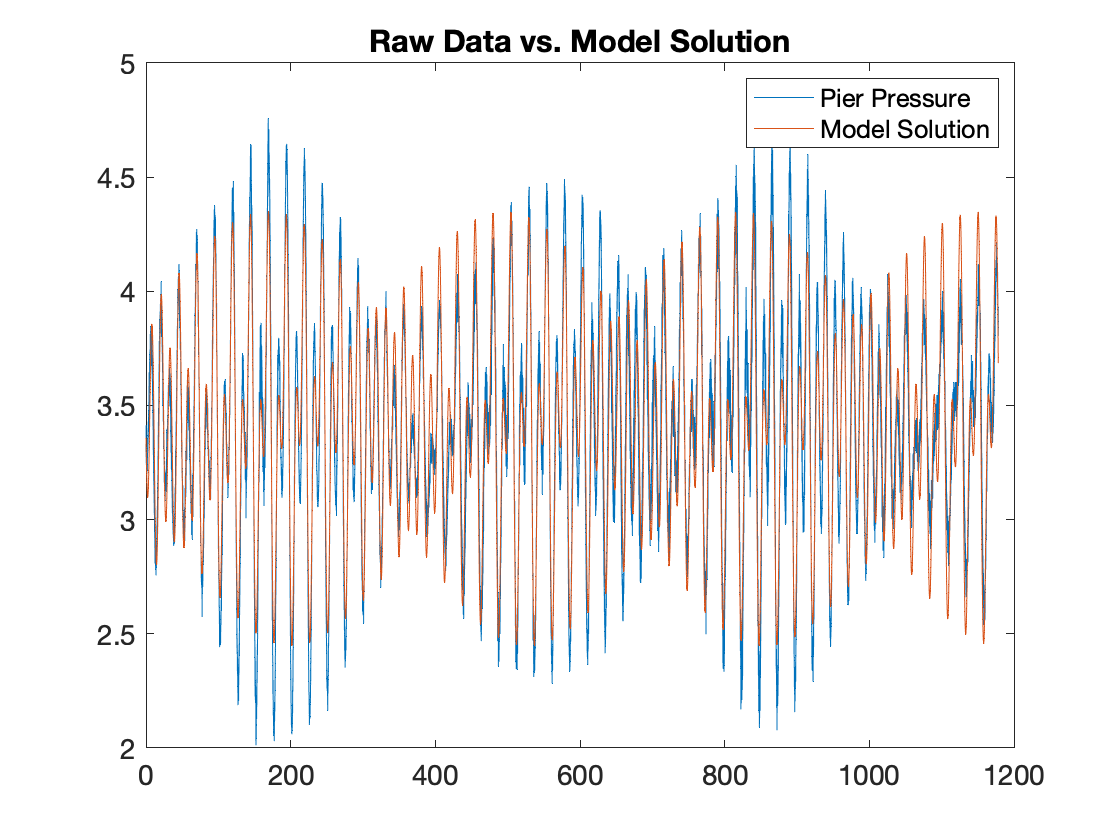


model = A2*x2;

figure(1)
clf
plot(time,data)
hold on
plot(time,model)
legend('Pier Pressure', 'Model Solution')
title('Raw Data vs. Model Solution')

3. Fourier transform. Now Fourier transform your data. (Don’t worry about any of the details of computing a spectrum for this exercise—just Fourier transform.) 

N=length(time);
dt=(4/60)/24;
T=dt*N;
df=1/T;
fn=1/2/dt;
f_vector=-fn:df:(fn-df); %frequency vector, cpd, goes from 0 to Nyquist.
f=fftshift(fft(data));

a. Plot the real and imaginary parts of the Fourier transform. Find the peaks. What frequencies correspond to these peaks? Are they what you’d expect based on the known tidal frequencies? 

- These are almost exactly what I would have expected based on the known tidal frequencies

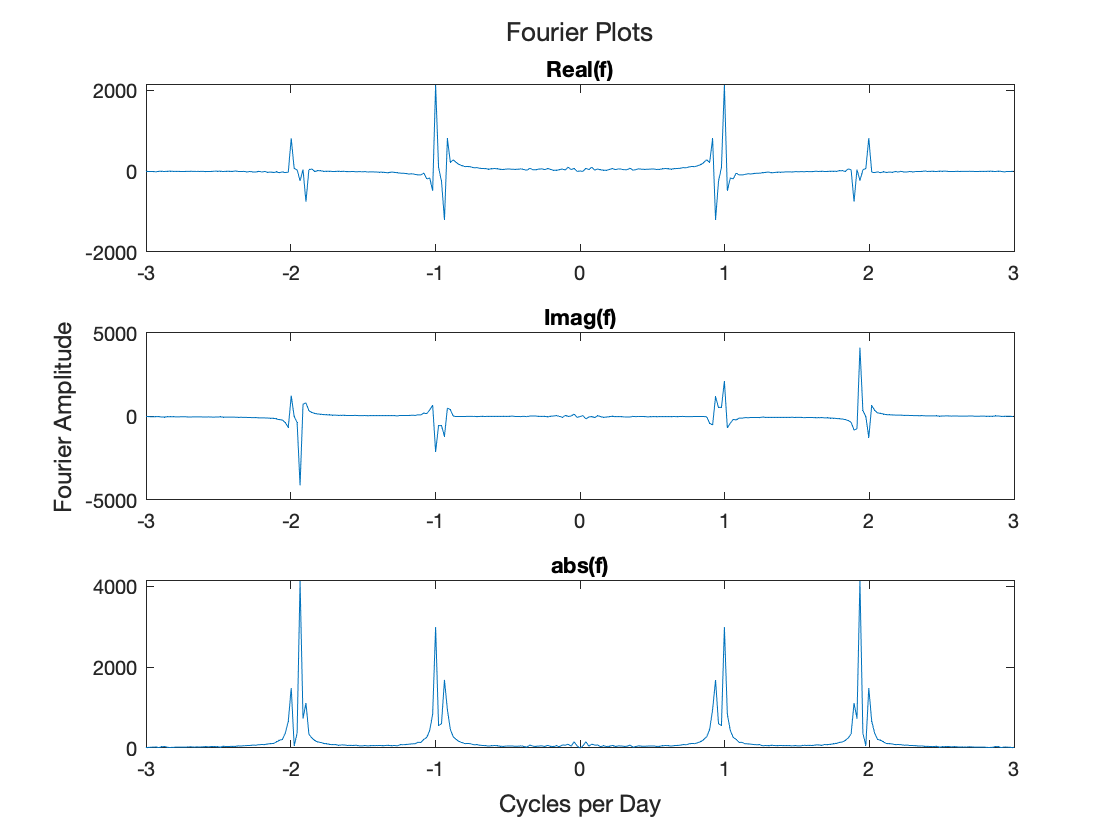

data = detrend(data); %detrend to remove crazy big peak
f=fftshift(fft(data));

figure(2) %detrended
clf
m = tiledlayout(3,1);
xlabel(m, 'Cycles per Day')
ylabel(m, 'Fourier Amplitude')
title(m, 'Fourier Plots')

nexttile
plot(f_vector,real(f))
xlim([-3 3])
title('Real(f)')

nexttile
plot(f_vector,imag(f))
xlim([-3 3])
title('Imag(f)')

nexttile
plot(f_vector,abs(f))
title('abs(f)')
xlim([-3 3])


%3 peak frqs:

f1 = 1/(0.93697/24)

f1 = 25.6145


f2 = 1/(0.998076/24)

f2 = 24.0463


f3 = 1/(1.93505/24)

f3 = 12.4028

b. Now use the Fourier coefficients to identify the mean pressure and the amplitudes of the major peaks. (Hint: to determine the amplitudes of the oscillatory modes, you’ll need to multiply by a factor of 2 to account for both the positive and negative frequencies.) 	

- The mean value is the one centered at 0 when the data is not detrended

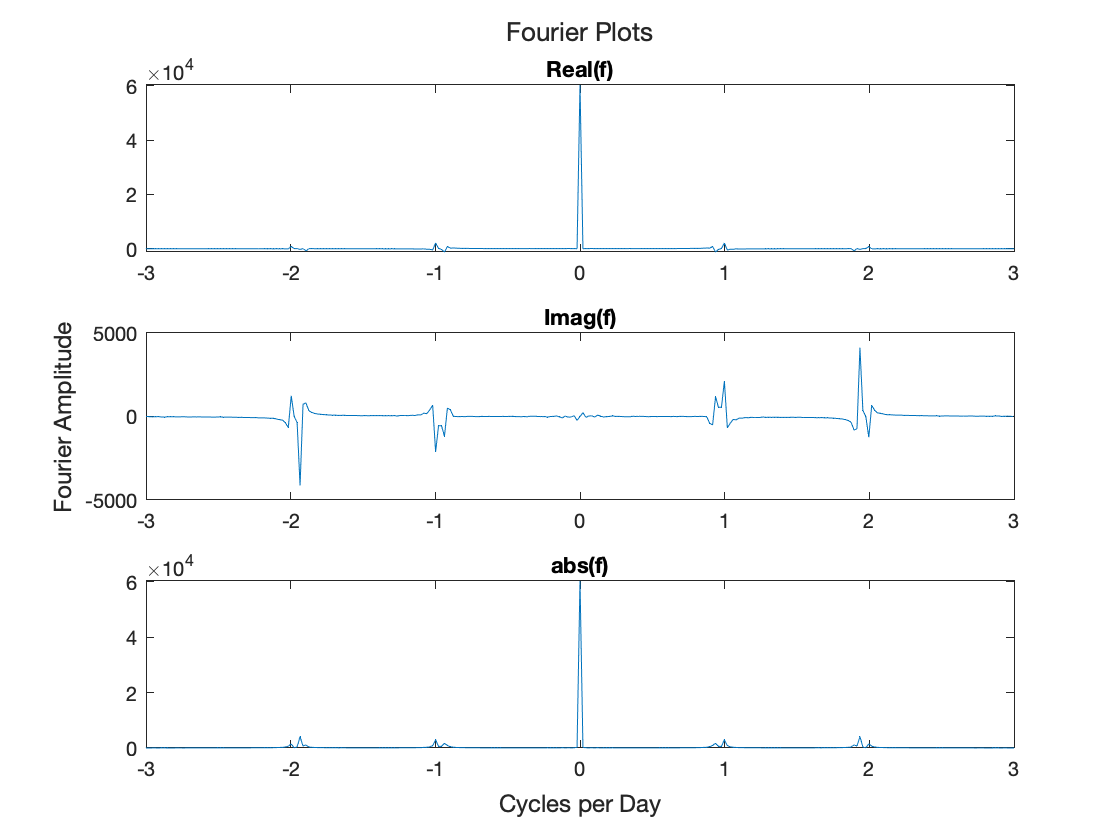

data = df2021.p2';
N=length(time);
dt=(4/60)/24;
T=dt*N;
df=1/T;
fn=1/2/dt;
f_vector=-fn:df:(fn-df); %frequency vector, cpd, goes from 0 to Nyquist.
f=fftshift(fft(data));

figure(3) %Not detrended
clf
m = tiledlayout(3,1);
xlabel(m, 'Cycles per Day')
ylabel(m, 'Fourier Amplitude')
title(m, 'Fourier Plots')

nexttile
plot(f_vector,real(f))
xlim([-3 3])
title('Real(f)')

nexttile
plot(f_vector,imag(f))
xlim([-3 3])
title('Imag(f)')

nexttile
plot(f_vector,abs(f))
title('abs(f)')
xlim([-3 3])


%3 peak frqs:

f1 = 1/(0.93697/24)

f1 = 25.6145


f2 = 1/(0.998076/24)

f2 = 24.0463


f3 = 1/(1.93505/24)

f3 = 12.4028


Mean = 60301.9

Mean = 6.0302e+04


Amplitudes = 2* [4134.48 2996.22 605.86]

Amplitudes = 	1.0e+03 *

    8.2690    5.9924    1.2117


c. Do these spectral peaks align with the results from the least-squares fit? Is there anything you could do to further check your results? 

- To test, I compared the fft of the model results and the real data and they align very well. I could find the r^2 value to quantify this fit if I wanted to.

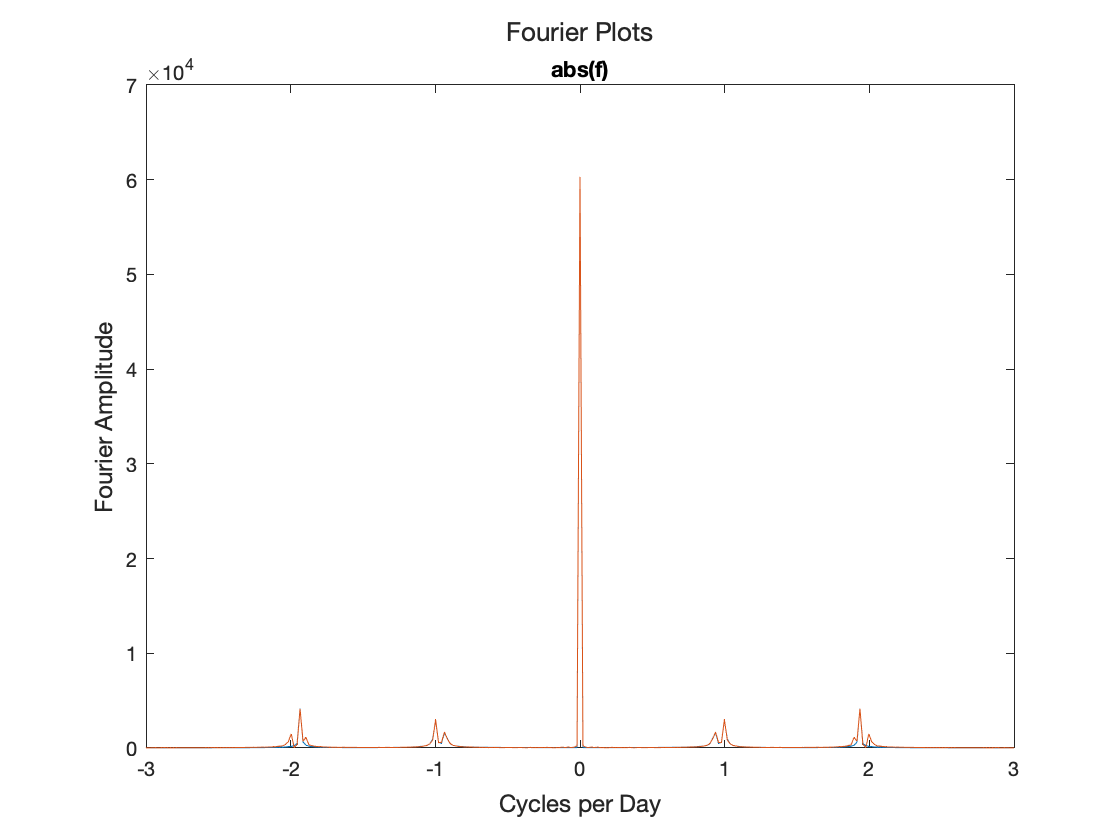

data = model;
N=length(time);
dt=(4/60)/24;
T=dt*N;
df=1/T;
fn=1/2/dt;
f_vector=-fn:df:(fn-df); %frequency vector, cpd, goes from 0 to Nyquist.
f_model=fftshift(fft(data));

figure(4) %Not detrended
clf
m = tiledlayout(1,1);
xlabel(m, 'Cycles per Day')
ylabel(m, 'Fourier Amplitude')
title(m, 'Fourier Plots')

nexttile
plot(f_vector,abs(f_model))
hold on
(plot(f_vector,abs(f)))
title('abs(f)')
xlim([-3 3])

d. Now plot the spectral energy (based on the squared magnitude of the Fourier coefficients) as a function of frequency. Is the spectrum red, white, or blue? 

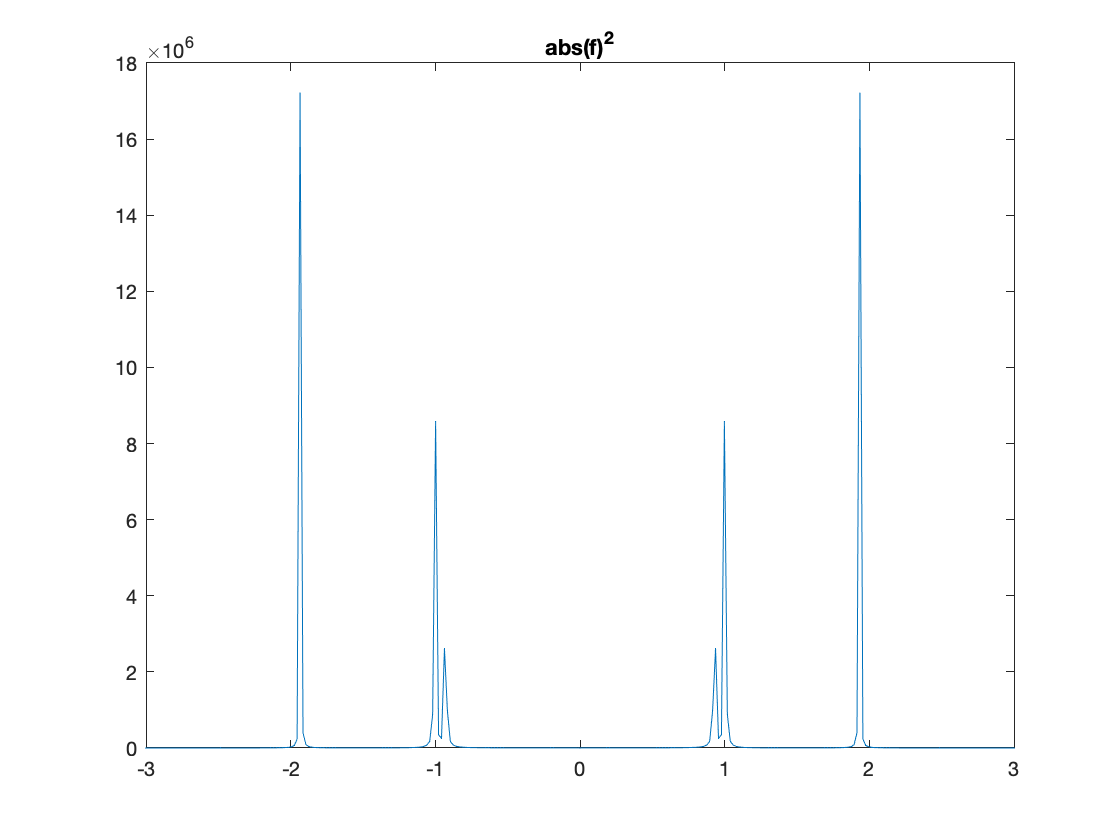

N=length(time);
dt=(4/60)/24;
T=dt*N;
df=1/T;
fn=1/2/dt;
f_vector=-fn:df:(fn-df); 
f=fftshift(fft(data));
data = detrend(data); 
f=fftshift(fft(data));
s_e = abs(f).^2;
figure(4)
clf
m = tiledlayout(1,1);

nexttile
plot(f_vector,abs(s_e))
title('abs(f)^2')
xlim([-3 3])

- This is red noise because the amplitude increases at a higher frequency.